% ss 狀態空間
% dx/dt = Ax + BI;
% theta = Cx + DI;
% 此ODE改寫ss

A = [0 1; -5 -2];
B = [0; 3];
C = [1 0];
D = 0;
H = ss(A, B, C, D);
H

H =
 
  A = 
       x1  x2
   x1   0   1
   x2  -5  -2
 
  B = 
       u1
   x1   0
   x2   3
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties



% FRD 頻率響應資料

freq = [10, 30, 50, 100, 500];
resp = [0.0021+0.0009i, 0.0027+0.0029i, 0.0044+0.0052i, 0.0200-0.0040i, 0.0001-0.0021i];
H = frd(resp, freq, 'Units', 'Hz');
H

H =
 
    Frequency(Hz)           Response       
    -------------           --------       
          10         2.100e-03 + 9.000e-04i
          30         2.700e-03 + 2.900e-03i
          50         4.400e-03 + 5.200e-03i
         100         2.000e-02 - 4.000e-03i
         500         1.000e-04 - 2.100e-03i
 
Continuous-time frequency response.
Model Properties



% 建立MIMO模型
s = tf('s'); % 先宣告是拉普拉斯
H = [1/(s+1), 0; (s+1)/(s^2 + s + 3), -4*s/(s+2)];
H

H =
 
  From input 1 to output...
         1
   1:  -----
       s + 1
 
          s + 1
   2:  -----------
       s^2 + s + 3
 
  From input 2 to output...
   1:  0
 
       -4 s
   2:  -----
       s + 2
 
Continuous-time transfer function.
Model Properties



size(H) % 知道多少輸入、輸出

Transfer function with 2 outputs and 2 inputs.


pole(H) % 計算極點

ans =   -1.0000 + 0.0000i
  -0.5000 + 1.6583i
  -0.5000 - 1.6583i
  -2.0000 + 0.0000i


isstable(H) % 詢問系統是否穩定

ans = logical
   1


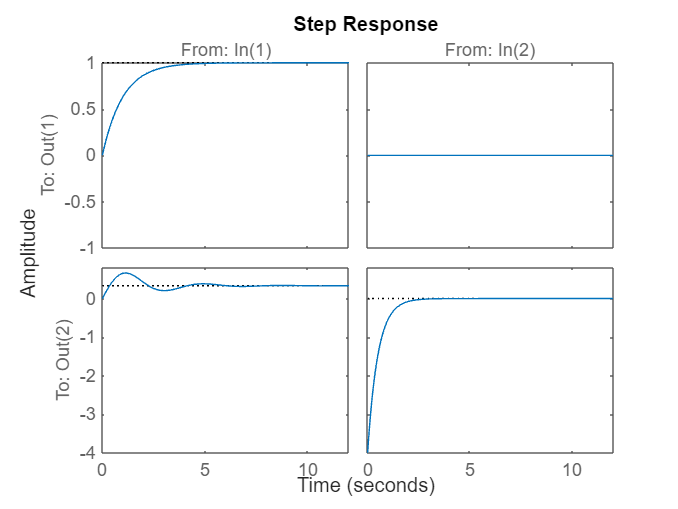

step(H) % 繪製步階響應